%This script filter the pixel ratio in differnt ways

%this part filter out the 10% sum of pixel value
outfolder = "D:\localData\trace_pipe_DJ\4088\test\rgc_color\top10pixsum";
inputfolder = "D:\localData\trace_pipe_DJ\4088\test\rgc_color\raw";
files = get_files_of_folder(inputfolder);
for i = 1:numel(files)
    myt = readtable(fullfile(inputfolder, files(i).name));
    A = table2array(myt);
    A_filtered = A(~any(A == 0, 2), :);%get rid of the zeros
    rowSum = sum(A_filtered, 2);
    N = size(A_filtered,1);
    k = ceil(0.1 * N);
    [~, idx] = sort(rowSum, 'descend');
    topQuarterRows = A_filtered(idx(1:k), :);

    % Filter the top quarter rows and save to a new table
    filtered_t = array2table(topQuarterRows);
    filtered_t.Properties.VariableNames = myt.Properties.VariableNames;
    [~, name, extension] = fileparts(files(i).name);
    newname = strcat(name, '_top10');

    newFilteredName = fullfile(outfolder, [newname extension]);
    writetable(filtered_t, newFilteredName);
end 


%interquantile of the color ratio
outfolder = "D:\localData\trace_pipe_DJ\4088\test\rgc_color\top10pixsum_intqratio";
inputfolder = "D:\localData\trace_pipe_DJ\4088\test\rgc_color\top10pixsum";
files = get_files_of_folder(inputfolder);

for i = 1:numel(files)
    tabledata = readtable(fullfile(inputfolder, files(i).name));
    norm1 = tabledata.c1./tabledata.c3;
    norm2 = tabledata.c2./tabledata.c3;

    low1 = prctile(norm1, 25);
    high1 = prctile(norm1, 75);
    

    low2 = prctile(norm2, 25);
    high2 = prctile(norm2, 75);
    f_norm1 = norm1(norm1>=low1 & norm1<=high1 & norm2>low2 & norm2<=high2);
    f_norm2 = norm2(norm1>=low1 & norm1<=high1 & norm2>low2 & norm2<=high2);

    newt = array2table([f_norm1 f_norm2]);
    newt.Properties.VariableNames = {'norm1', 'norm2'};
    [~, name, extension] = fileparts(files(i).name);
    newname = strcat(name, '_quntilenorm');

    newFilteredName = fullfile(outfolder, [newname extension]);
    writetable(newt, newFilteredName)
end

% median absolute deviation

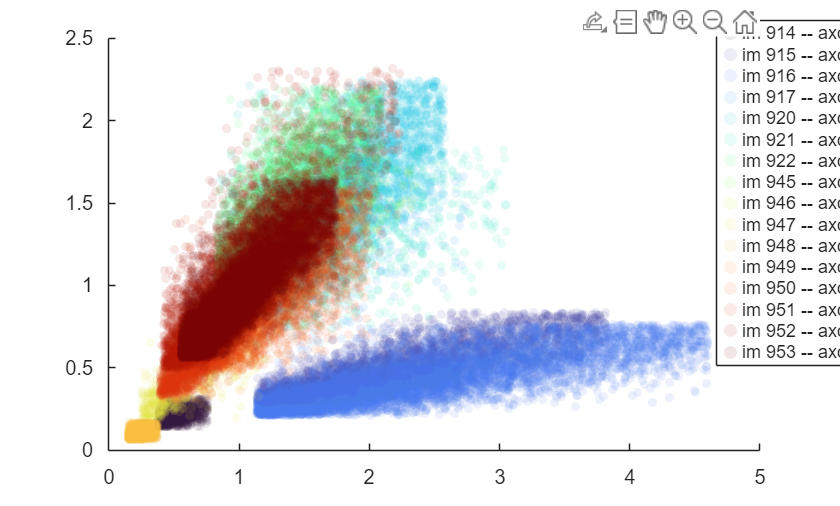

%scatter plot the folder -- brain, all pixel
inputfolder = "D:\localData\trace_pipe_DJ\4088\test\brain_color\pixel\pixsum_top10_ratioInterquantile";
animal_id = 4088;
qs = sprintf('animal_id = %d', animal_id);
all_axons = fetch(sln_image.AxonImageAssociation*sln_cell.Axon & qs);
files = get_files_of_folder(inputfolder);
colors = turbo(numel(files));
figure;
hold on;
mylegend = cell(numel(files), 1);
for i = 1:numel(files)
    tabledata = readtable(fullfile(inputfolder, files(i).name));
    vn = tabledata.Properties.VariableNames;
    tokens = regexp(files(i).name, '^(\d+)_', 'tokens');
    image_id = str2double(tokens{1}{1});
    if (numel(vn)~=2)
        warning('You are plotting 2D but the table has more than 2 variables\n');
    end
    n1 = vn{1};
    n2 = vn{2};
    markersize  = 16;
    scatter(tabledata.(n1), tabledata.(n2), markersize, 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', colors(i, :),...
         'MarkerFaceAlpha', 0.1, 'MarkerEdgeAlpha',0.1);
    axon_idx = [all_axons.image_id] == image_id;    
    l =  sprintf('im %d -- axon %d', image_id,all_axons(axon_idx).axon_id);
    mylegend{i} = l;

end
legend(mylegend);
hold off;

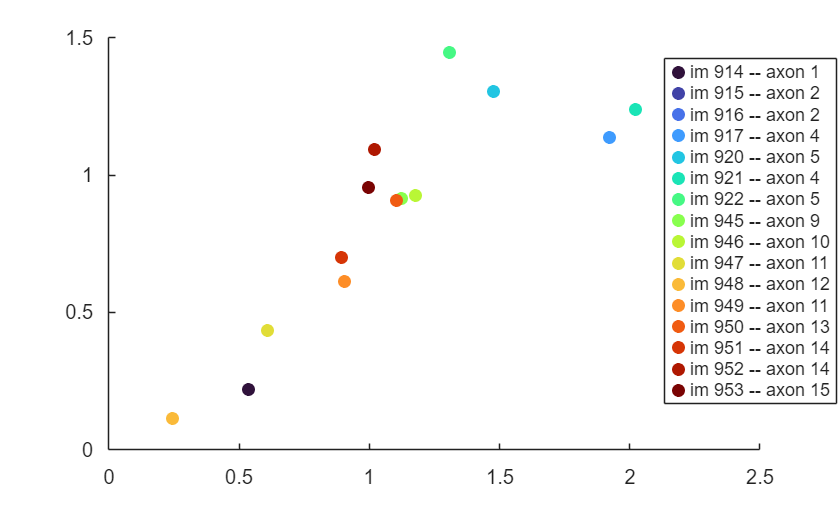

%scatter plot the folder -- brain, only mean
inputfolder = "D:\localData\trace_pipe_DJ\4088\test\brain_color\pixel\pixsum_top10_ratioInterquantile";
animal_id = 4088;
qs = sprintf('animal_id = %d', animal_id);
all_axons = fetch(sln_image.AxonImageAssociation*sln_cell.Axon & qs);
files = get_files_of_folder(inputfolder);
colors = turbo(numel(files));
figure;
hold on;
mylegend = cell(numel(files), 1);
for i = 1:numel(files)
    tabledata = readtable(fullfile(inputfolder, files(i).name));
    vn = tabledata.Properties.VariableNames;
    tokens = regexp(files(i).name, '^(\d+)_', 'tokens');
    image_id = str2double(tokens{1}{1});
    if (numel(vn)~=2)
        warning('You are plotting 2D but the table has more than 2 variables\n');
    end
    n1 = vn{1};
    n2 = vn{2};
    scatter(mean(tabledata.(n1)), mean(tabledata.(n2)), 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', colors(i, :));
    axon_idx = [all_axons.image_id] == image_id;    
    l =  sprintf('im %d -- axon %d', image_id,all_axons(axon_idx).axon_id);
    mylegend{i} = l;

end
legend(mylegend);
hold off;

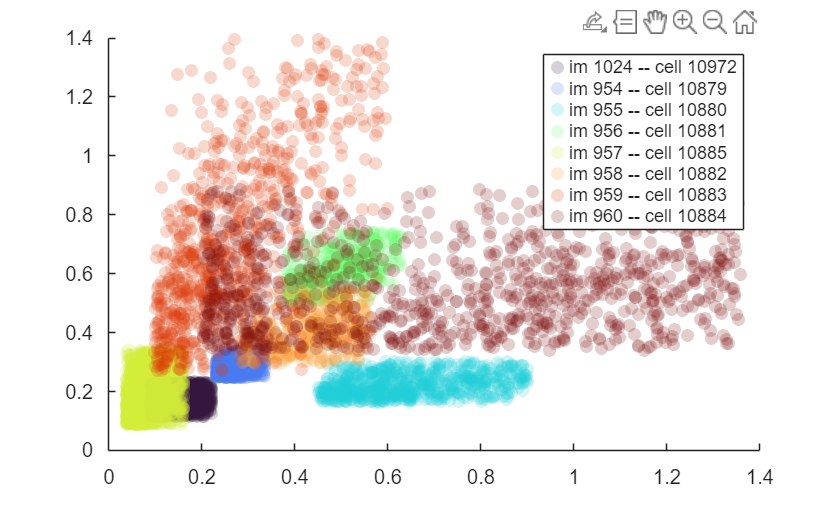

%scatter plot the folder -- rgc
inputfolder = "D:\localData\trace_pipe_DJ\4088\test\rgc_color\top10pixsum_intqratio";
animal_id = 4088;
qs = sprintf('animal_id = %d', animal_id);
all_rgcs = fetch(sln_cell.RetinalCell * sln_image.RetinalCellImage*sln_image.RGCinRetina & qs);
files = get_files_of_folder(inputfolder);
colors = turbo(numel(files));
figure;
hold on;
mylegend = cell(numel(files), 1);
for i = 1:numel(files)
    tabledata = readtable(fullfile(inputfolder, files(i).name));
    vn = tabledata.Properties.VariableNames;
    tokens = regexp(files(i).name, '^(\d+)_', 'tokens');
    image_id = str2double(tokens{1}{1});
    if (numel(vn)~=2)
        warning('You are plotting 2D but the table has more than 2 variables\n');
    end
    n1 = vn{1};
    n2 = vn{2};
    scatter(tabledata.(n1), tabledata.(n2), 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', colors(i, :),...
         'MarkerFaceAlpha', 0.2, 'MarkerEdgeAlpha',0.2);
    rgc_idx = [all_rgcs.image_id] == image_id;    
    l =  sprintf('im %d -- cell %d', image_id, all_rgcs(rgc_idx).cell_unid);
    mylegend{i} = l;

end
legend(mylegend);
hold off;

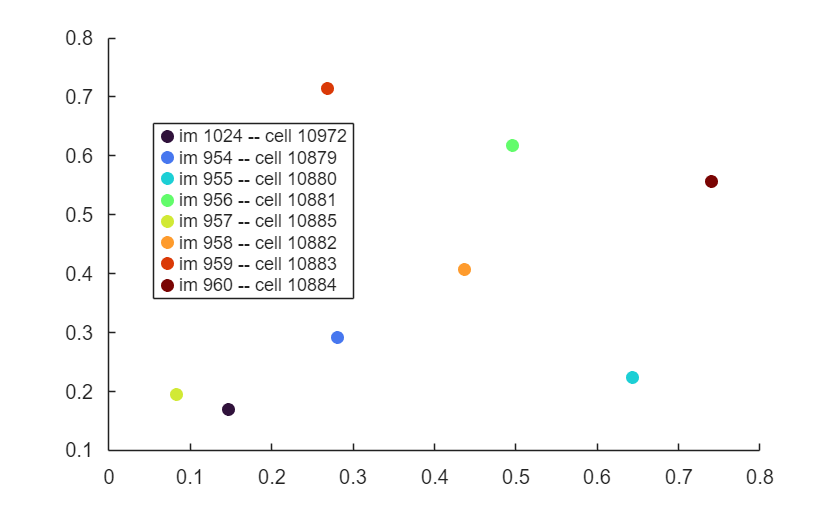

%scatter plot the mean of the folder
inputfolder = "D:\localData\trace_pipe_DJ\4088\test\rgc_color\top10pixsum_intqratio";
animal_id = 4088;
qs = sprintf('animal_id = %d', animal_id);
all_rgcs = fetch(sln_cell.RetinalCell * sln_image.RetinalCellImage*sln_image.RGCinRetina & qs);
files = get_files_of_folder(inputfolder);
colors = turbo(numel(files));
figure;
hold on;
mylegend = cell(numel(files), 1);
for i = 1:numel(files)
    tabledata = readtable(fullfile(inputfolder, files(i).name));
    vn = tabledata.Properties.VariableNames;
    tokens = regexp(files(i).name, '^(\d+)_', 'tokens');
    image_id = str2double(tokens{1}{1});
    if (numel(vn)~=2)
        warning('You are plotting 2D but the table has more than 2 variables\n');
    end
    n1 = vn{1};
    n2 = vn{2};
    scatter(mean(tabledata.(n1)), mean(tabledata.(n2)), 'MarkerFaceColor', colors(i, :), 'MarkerEdgeColor', colors(i, :));
    rgc_idx = [all_rgcs.image_id] == image_id;    
    l =  sprintf('im %d -- cell %d', image_id, all_rgcs(rgc_idx).cell_unid);
    mylegend{i} = l;

end
legend(mylegend);
hold off;